# **Redes Multicapa**

**Objetivo **

Crear predictor de IPC (Índice de Precios y Cotizaciones) lo cual implica trabajar con datos históricos y analizar las tendencias para poder predecir el comportamiento del mercado bursátil en el futuro y utilizar esta información para tomar decisiones informadas sobre inversiones y estrategias empresariales.

prever cómo se comportará el mercado bursátil en el futuro. El IPC es un índice que refleja la variación de los precios de las acciones de las empresas más importantes que cotizan en la Bolsa Mexicana de Valores (BMV), por lo que un predictor de IPC podría ser utilizado para predecir el comportamiento del mercado de valores en México.

- Obtén datos históricos

- Analiza los datos

- Elige un modelo de predicción

- Entrena el modelo

- Valida el modelo

- Utiliza el modelo para hacer predicciones

- Actualiza el modelo

Limpiar el entorno. 

clear all
close all
clc

Cargar los datos 4 (datos históricos de los precios de las acciones de las empresas que componen el índice)

contiene datos sobre los precios de las acciones de diferentes empresas que cotizan en la Bolsa Mexicana de Valores. El conjunto de datos tiene las siguientes variables:

- Fecha: La fecha en que se registraron los precios de las acciones.

- Clave de cotización: El código de identificación de la empresa que emite las acciones.

- Emisora: El nombre de la empresa que emite las acciones.

- Serie: El tipo de acciones emitidas por la empresa (por ejemplo, "A" para acciones ordinarias y "B" para acciones preferentes).

- Precio de apertura: El precio de apertura de las acciones en el mercado.

- Precio de cierre: El precio de cierre de las acciones en el mercado.

- Precio más bajo: El precio más bajo que alcanzaron las acciones durante el día.

- Precio más alto: El precio más alto que alcanzaron las acciones durante el día.

- Volumen: El número de acciones que se negociaron durante el día

Extraer valores finales

ipc = readtable('Datos_IPC_5a.csv');

numero de delays (retrasos o desfases)

 "delays" se refieren a los retrasos o desfases que se producen en la predicción de los precios de las acciones. Es decir, el modelo de predicción puede no ser capaz de capturar todas las fluctuaciones del mercado en tiempo real y puede haber una demora en la predicción de los precios de las acciones.

data = ipc(:,2:end);
data = table2array(data);

data = 1.0e+03 *

    0.0791    0.0146    0.0501    0.0123    0.2805    0.0194    0.0321    0.0312    0.0071    0.0260    0.0328    1.3590    0.1500    0.1778    0.0696    0.0960    0.0168    0.0241    0.0755    0.0399    0.1746    0.0284    0.0919    0.0151    0.0219    0.0834    0.0574    0.1054    0.0364    0.2065    0.1587    0.0622    0.0821    0.0402    0.0332    0.0471
    0.0798    0.0148    0.0505    0.0126    0.2819    0.0196    0.0321    0.0305    0.0071    0.0254    0.0327    1.3554    0.1515    0.1787    0.0701    0.0955    0.0166    0.0241    0.0757    0.0400    0.1762    0.0284    0.0926    0.0151    0.0219    0.0849    0.0574    0.1049    0.0370    0.2108    0.1615    0.0620    0.0815    0.0403    0.0338    0.0467
    0.0795    0.0149    0.0505    0.0125    0.2767    0.0195    0.0323    0.0304    0.0071    0.0252    0.0328    1.3646    0.1514    0.1772    0.0704    0.0948    0.0167    0.0243    0.0758    0.0391    0.1741    0.0286    0.0921    0.0151    0.0217    0.0854


temp=bsxfun(@minus,data,mean(data)); %Subtract the average of each columma
data=bsxfun(@rdivide,temp,std(data)); %Divide by standard deviation
% Creation of the competitive network
nn=4; %Number of neurons
red=competlayer(nn); %Create competitive network
red.trainParam.epochs=100; %Define epochs and other parameters
red=train(red,data); %network training

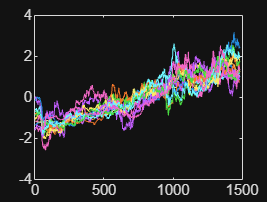

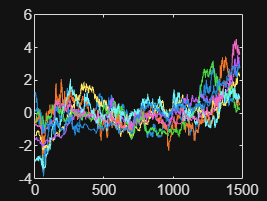

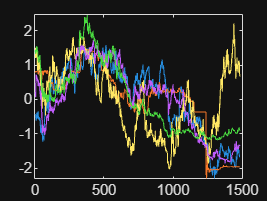

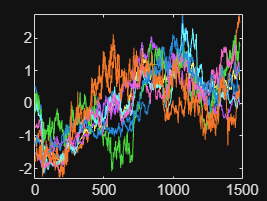

Wf=red.IW{1,1}'; %Final weights
% Simulación de datos
Y=red(data);
Y=vec2ind(Y); %converts vectors to indexes
grupos=unique(Y);
for k=1:size(grupos,2)
    temp=data(:,Y==grupos(1,k));
    eval(sprintf('grupo%d=temp;',k));
    figure;
    eval(sprintf('plot(grupo%d);',k));
end

ciclo "for" para almacenar los datos de entrada retrasados en el tiempo, la primera columna corresponde a los datos en el tiempo actual y las columnas restantes corresponden a los datos retrasados.

¿Cómo se comportarán los precios de las acciones en el futuro?

Los inversores y las empresas utilizan esta información para tomar decisiones informadas sobre cómo invertir su dinero. Un predictor de IPC preciso puede ayudar a los inversores a identificar oportunidades de inversión y tomar decisiones estratégicas en el mercado de valores. Por otro lado, las empresas pueden utilizar la información del predictor para planificar su estrategia empresarial y financiera.